# Interval Notations and Examples

When we look at the problem facing a household, we often have to restrict the choice set for example to an interval. 

## Closed Interval

For example, if $x$ is hours working, perhaps the household has to work at least $a$ hours and up to $b$ hours, so his choice is between $a$ and $b$ hours inclusive.

The interval that is inclusive of both endpoints is called a closed interval (note the square brackets):

- **closed interval**: $\left[ a, b \right] \equiv \{ x \in \mathbf{R} : a \le x \le b\}$

## Open Interval With 2 Period Savings Example

Suppose we have a household who will have no income tomorrow, but has $b$ dollar income income today. He needs to determine how much to save.

If she saves $0$ today, she will die tomorrow due to hunger. If she saves all $b$ today, she will die of hunger today. Mathmatically, we could use log utility to describe this $0$ state of desperation. As consumption gets close to $0$, utility goes towards negative infinity, and utility is not defined at $0$.

We can write down the model where we maximize utility over choices $x_{today}, x_{tomorrow}$:

- **Utility**: $U(c_{today}, c_{tomrrow}) = \log(c_{today}) + 0.95 \cdot \log(c_{tomorrow})$

- **Budget Today**: $c_{today} + save = b$

- **Budget Tomorrow**: $c_{tomorrow} = save\cdot (1+ 0.03 )$

Maximization Problem:

- 
$$\max_{save} \left\{ \log(b-save) + 0.95 \log(save \cdot (1 + 0.03) ) \right\}$$


*Note*: $0.95$ is the discount rate, and 1.03 is the interest rate on savings.

*Note*: the only choice in this model is $save$, that will determine consumption today and tomorrow.

Even though the budget constraint seems to allow for $0$ consumption today and tomorrow, but $\log$ utility is not defined at $0$, hence the maximization problem is undefined at $x_{today}=0$ and $x_{tomorrow}=0$. Hence, the actual choice set for $save$ is an open interval:

- $save \in ( 0, b )$, (*which means *$0$* and *$b$* are not in the domain*)

Our Maximization problem is hence:

- 
$$\max_{save \in (0, b) } \left\{ \log(b-save) + 0.95 \log(save \cdot (1 + 0.03) ) \right\}$$


Note here we use parenthesis, not square brackest. In general, an open interval is defined as:

- **open interval**:$\left( a, b \right) \equiv \{ x \in \mathbf{R} : a < x < b\}$

## Half Open and Half Close Interval

We can also hafl half open intervals:

- **half open (half closed) interval**: $\left[ a, b \right) \equiv \{ x \in \mathbf{R} : a \le x < b\}$

- **half open (half closed) interval**: $\left( a, b \right] \equiv \{ x \in \mathbf{R} : a < x \le b\}$

## Graph

If you were to graph an interval, you can draw an empty circle at either end of an interval that is open, and a solid circle if it is closed at that end. 

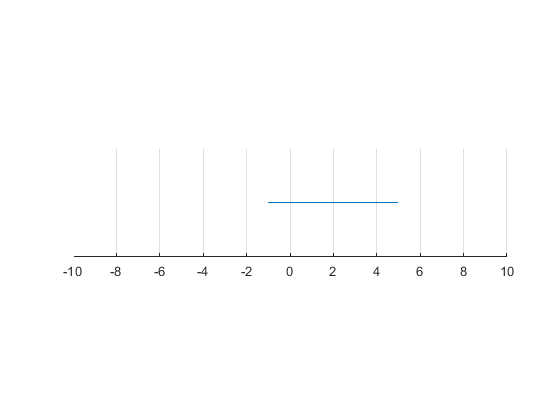

close all;
figure();
x = linspace(-1,5);
line(x,0*ones(size(x)))
set(gca,'ytick',[],'Ycolor','w','box','off')
ylim([-0.1 0.1])
xlim([-10  10])
pbaspect([4 1 1])
grid on